目的関数をワーカーにコピー中...
目的関数をワーカーにコピーしました。
|=========================================================================================================================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |         beta |       W_in_a |        alpha |      eig_rho |            n |            k |           kb |           pb |
|      | workers | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |              |              |              |              |
|=========================================================================================================================================================================================================|
|    1 |       4 | Best   |      7880.3 |      14.868 |      7880.3 |      7880.3 |    0.0011091 |      0.32414 |     0.038767 |      0.79079 |    

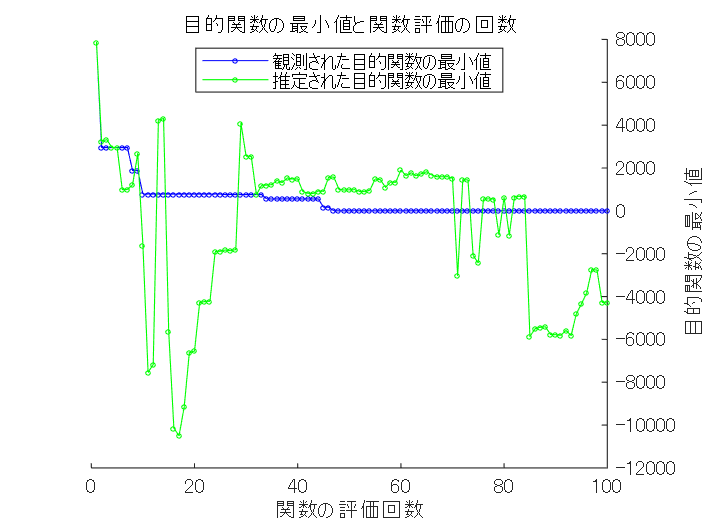


__________________________________________________________
最適化が完了しました。
MaxObjectiveEvaluations の 100 に達しました。
関数の評価回数の合計: 100
経過時間の合計: 459.0535 秒
目的関数の評価時間の合計: 1646.0257

最適な観測実行可能点:
      beta       W_in_a     alpha     eig_rho     n     k      kb          pb   
    _________    ______    _______    _______    ___    _    _______    ________

    0.0028239    1.657     0.53512    0.30944    101    1    0.60256    0.074062

観測された目的関数値 = 0
推定される目的関数値 = 5718.0794
関数の評価時間 = 7.533

最適な推定実行可能点 (モデルに基づく):
       beta       W_in_a      alpha     eig_rho     n     k      kb          pb   
    __________    _______    _______    _______    ___    _    _______    ________

    0.00014885    0.46851    0.95403    0.44839    126    1    0.89704    0.077026

推定される目的関数値 = -4289.3949
推定される関数評価時間 = 6.5024



% ベイズ最適化用の目的関数
function score = objective_function(params)
   % ハイパーパラメータの取得
   beta = params.beta;
   W_in_a = params.W_in_a;
   alpha = params.alpha;
   eig_rho = params.eig_rho;
   n = params.n;
   k = params.k;
   kb = params.kb;
   pb = params.pb;

   %パラメータ設定
   numNode = 10; %ノード数
   completeGraph = complete_graph(numNode); %N_node個のノードを持つ完全グラフ
   adjacencyMatrix = adjacency(completeGraph); %completeGraphの隣接行列
   omega = 3; %固有振動数
   dencityBetweenNodes = 8; %ノード間の結合密度
   p = 0:0.1:1; %不活性ノードの割合
   activeNode = 1; %活性ノードの自己振幅係数
   inactiveNode = -1; %不活性ノードの自己振幅係数
   t_max = 600;
   dt = 0.05;
   t_steps = t_max / dt;
   t = linspace(0, t_max, t_steps);
   ntrans = 6000; %過渡期
   pred_time = 3000;
   train_param = [0.1 0.2 0.3];
   z_initial = ones(numNode, 1) + 1i * ones(numNode, 1); %初期値 1 + 0*i
   z_initial = [real(z_initial); imag(z_initial)]';
   dim = numNode*2; %ノード数の実部と虚部
   z_data = solve_model(t_steps, ntrans, dim, t, train_param, numNode, ...
       activeNode, inactiveNode, z_initial, omega, dencityBetweenNodes, adjacencyMatrix)';
   Nt = 4500;  % training length
   Np = 400;    % predicting length
   wa = 100;    % warmup length
   transit = 50; % abandon reservoir length
   ESN_par = [n, alpha, beta, Nt, Np, transit, dim];
   W_input = W_inn(n, dim, W_in_a);
   W_reservoir = W_ress(k, n, eig_rho);
   W_out = create_ESN(ESN_par, z_data, train_param, W_input, W_reservoir, kb, pb);
   mse_values = zeros(size(p)); % 各 epsilon に対する MSE を格納
   sum_node_values = zeros(1,numNode);
   for ind_par = 1:length(p)
       z_data = solve_model(t_steps, ntrans, dim, t, p(ind_par), numNode, ...
           activeNode, inactiveNode, z_initial, omega, dencityBetweenNodes, adjacencyMatrix)';
       pred_data = prediction(pred_time, alpha, n, p(ind_par), z_initial, W_out, W_reservoir, W_input, kb, pb, numNode);
                
       % 実部と虚部を取り出して複素数に戻す
       real_part_real = z_data(1:2:end, :); % 偶数番目が実部
       real_part_pred = pred_data(1:2:end, :); % 偶数番目が実部
        
       for i = 1:numNode
           % 極大値の検出
           [target_peaks, ~] = findpeaks(real_part_real(i,:));
           [pred_peaks, ~] = findpeaks(real_part_pred(i,:));
    
           %ピークがない時の処理
           if isempty(target_peaks) || isempty(pred_peaks)
               mse_values(ind_par) = NaN;
               continue;
           end
            
           % 両方の極大値リストの短い方に合わせる
           min_length = min(length(target_peaks), length(pred_peaks));
           target_peaks = target_peaks(1:min_length);
           pred_peaks = pred_peaks(1:min_length);

           % 極大値のMSE計算
           mse_peak = @(pred, target) sum((pred - target).^2, 'all');
           sum_node_values(i) = mse_peak(pred_peaks, target_peaks);
       end
       mse_values(ind_par) = sum(sum_node_values);
   end

   % MSE の合計を最終スコアとする
   score = sum(mse_values);
end

% 最適化するハイパーパラメータの定義
vars = [
   optimizableVariable('beta', [1e-5, 1e-2], 'Transform', 'log');
   optimizableVariable('W_in_a', [0.1, 3]);
   optimizableVariable('alpha', [0, 1]);
   optimizableVariable('eig_rho', [0, 1]);
   optimizableVariable('n', [100, 1000], 'Type', 'integer');
   optimizableVariable('k', [1, 20], 'Type', 'integer');
   optimizableVariable('kb', [0, 1]);
   optimizableVariable('pb', [0, 1]);
];


% ベイズ最適化の実行
results = bayesopt(@objective_function, vars, ...
                  'MaxObjectiveEvaluations', 100, ...
                  'IsObjectiveDeterministic', false, ...
                  'UseParallel', true);


% 最適なハイパーパラメータの取得
best_params = results.XAtMinObjective;
disp(best_params);

      beta       W_in_a     alpha     eig_rho     n     k      kb          pb   
    _________    ______    _______    _______    ___    _    _______    ________

    0.0028239    1.657     0.53512    0.30944    101    1    0.60256    0.074062

